# Exercise 2

## Probabilistic Mapping With the LIDAR Sensor

### About This Exercise

If the goal is to map a space, then using the bump sensor is very inefficient. It is like feeling around in the dark, slowly and carefully moving your hands along the wall until you find the light switch. Once the lights are on, your vision allows you to rapidly map out the rest of the entire room. Range sensors are similar, as they not only detect the presence of objects at a distance, but also the absence of any objects in-between. In this exercise, you will build the map using the LIDAR range sensor data.

As the LIDAR uses light, the beam that it emits and the returning signal are relatively narrow. Thus, while only a single distance is being returned, there is uncertainty in the exact angle of where the object is. The beam roughly is cone shaped, where the closer the object, the less uncertainty there is for the angular direction. You will first develop a function that takes in the robot pose and sensor data (angle and measured distance) and returns the log-odds updates for each cell in the map based on the inverse sensor model cone that was discussed in the videos. You will then use this function to map the same environment as in the previous exercise.

**By the end of this exercise, you'll be able to: **

- **Use probabilistic mapping to update an occupancy grid that builds a map based on LIDAR data **

### Range Inverse Sensor Model

The first step is to create a function that takes in the current log-odds of the map as well as the prior, the current pose of the robot, the current measurements, and some sensor parameters, and returns the updated log-odds for all cells in the map. You will need to generate the sensor cone and find which cells in the map intersect with the free and occupied areas of the cone.

[► Complete the logOddsLidar function](matlab:open('./logOddsLidar.mlx'))

Once complete, run the code below to test one observation.

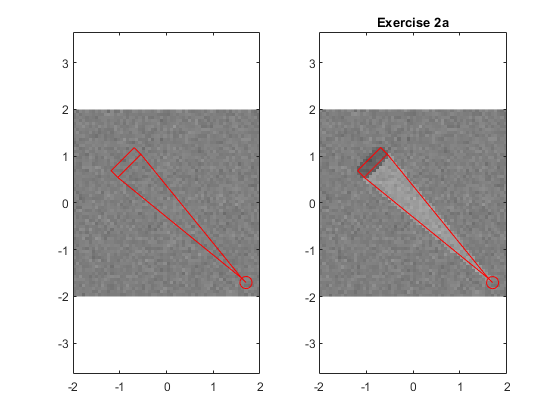

gridsize = 60; %Change value here
dist = 3.5; %Change value here
lim = 2; %Change value here
mapsize = 4;
x = linspace(-mapsize/2,mapsize/2,gridsize+1);
y = x;
[X,Y] = meshgrid(x,y);
Zlast = .1*randn(gridsize);
Zprior = zeros(gridsize);
pose = [1.7,-1.7,3*pi/4];
ang = 0;
[Z,hitbox,cone] = logOddsLidar(X,Y,Zlast,Zprior,pose,ang,dist,0.13,4);
plot_title = "Exercise 2a"; 
plotOddsLidarUpdate(X,Y,Zlast,Z,lim,pose,hitbox,cone, plot_title);

### visitWaypointsMapping

Finally, lets use our mapping function in the Simulator to generate the same map as the previous exercise but now with the Lidar sensor.

[► Complete the visitWaypointsMapping function](matlab:open('./visitWaypointsMapping.mlx'))

Once complete

1) Run the simulator, 

2) Load up the same map called Map104S.txt, 

3) Set the starting position in the top corridor facing east, and start the automatic control function. 

4) Change the gridsize and the color limits to see the effect on the map.

Do you see any issues with this inverse sensor function? Draw out what should happen when the laser hits a wall at an angle. What problem does this cause and how might you adapt the inverse sensor model? If you want you can try making such improvements to the inverse sensor model.

### Finished!

You can now make probabalistic maps using different types of sensors. For these exercises, we have assumed knowledge of the robot pose in order to build the map. In the next set of exercises, you will explore how to localize while mapping an unknown environment and develop two algorithms for simultaneous localization and mapping (SLAM).